The purpose of this live script is to analyze the effect of Thomson scattering. This type is valid during the case where  photon energy is much cmaller than mass energy of the particle. Or in this case, where the wavelength of light is much greater than the Compton wavelength. We see in example one that for light in the visible spectrum Compton scattering does little. Here, we are in a low energy limit of Compton scattering, where the kinetic energy and photon frequency do not change as a result of scattering. What causes scattering here is the photon accelerates the charged particle, causing it to emit radiation and therefore scatter. In this scenario we need to choose a range of photon wavelengths and a particle which these wavelengths will scatter. Here let's choose the visual spectrum 400-750nm and the particle will be an electron.

clear all
close all
%first set up the particle parameters
e_charge=1.60217*(10.^-19); %[C]
e_mass=9.109383*(10.^-31); %[Kg]
%the following is built into the cross section FCN
permittivity_coef=4*pi*(8.854187*10.^-12);

Thomson scattering takes incident flux as an input and not a particle wavelength like Compton scattering does. For this reason we now need to define our indident flux. This requires four different variables: Energy, time, area and wavelength. We also require the information regarding particle density and particle type the latter of which we've defined already. Let's set up our variables.

%variable initialisation
energy=1400000; %[J]
time=10; %[s]
area=100; %[m^2]
particle_density=6.0221367*(10^23);%[p/m^3]
chi=30; %[degrees] angle from incident to observer

Note that I've chosen the above parameters to reflect the incident flux which the Sun delivers to Earth. Play with these parameters at your leasure, maybe increase the power to that which Mercury receives and see how scattering is affected. Change the particle density as well to observe the affects of this change. Examine the formula to predict their effects. 

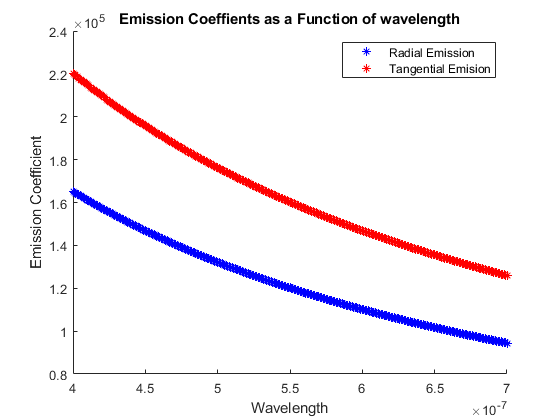

%first let's find out how different wavelengths
%change the scattering.

%examing the Thomson cross section for an electron
t_cross_sec=thomson_cross_section(e_charge,e_mass);

k=1;
%let's try some values, Thomson cross section built into FCN below
for i=400:1:700
    [radial_em(k),tangential_em(k)]=thomson_emission_coefficients(energy,time,...
        area,i*(10.^-9),particle_density,e_mass,e_charge,chi);
    wavelength(k)=i*(10.^-9);
    k=k+1;
end

%we now want to plot these as a function of wavelength
hold on
plot(wavelength,radial_em,'b*')
plot(wavelength,tangential_em,'r*')
title('Emission Coeffients as a Function of wavelength')
xlabel('Wavelength')
ylabel('Emission Coefficient')
legend('Radial Emission','Tangential Emision')
hold off

What do we notice here? Well it appears that blue light scatters more than red light, which is consistent with basic scattering knowledge, looks like we've done a good job, let's now play around with some parameters and plot this in a heat map so we can simultaneously observe the effect of two parameters. To begin, how about wavelength and area?

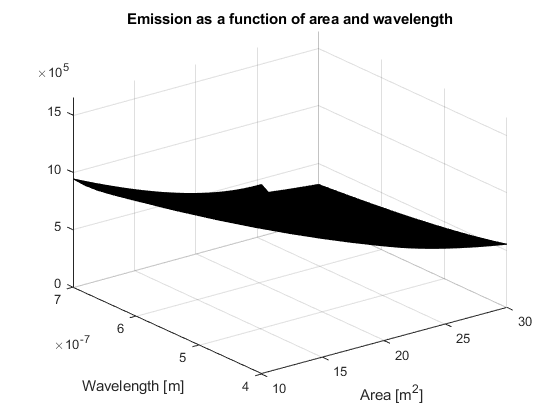

%let's go ahead and observe the effect of wavelength and area changing
%simultaneously

k=1;
l=1;
for j=10:1:30 %range of area values in m^2
    %fprintf('Area %d calculation complete \n',j)
    k=1;
    for i=400:1:700 %range of values *10^-9
        [radial_em2(k,l),tangential_em2(k,l)]=thomson_emission_coefficients(energy,time,...
            j,i*(10.^-9),particle_density,e_mass,e_charge,chi);
        wavelength2(k)=i*(10.^-9);
        k=k+1;
    end
    area(l)=j;
    l=l+1;
    
end

%in order to view and play with this plot a bit more open it up in a figure
%window. It's one of the options in the display to the right
surf(area,wavelength2,radial_em2)
title('Emission as a function of area and wavelength')
xlabel('Area [m^2]')
ylabel('Wavelength [m]')

As we can observe here scattering decreases as the area increases as there is less intensity of light to scatter. Scattering increases with wavelength just as we expect and showed in the previous graph. Let's now move on and test some other parameters, how about we change the particle charge and particle mass. This is a theoretical experiment and the mass/charge combinations may not exist in reality, but we are building intuition about scattering here, not solving problems. 

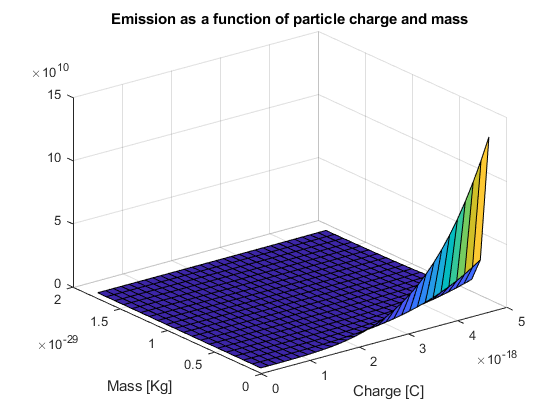

%let's go ahead and observe the effect of wavelength and area changing
%simultaneously

k=1;
l=1;
for j=1:1:30 %range of scales for particle charge
    %fprintf('Area %d calculation complete \n',j)
    k=1;
    for i=1:1:20 %range of scales for particle mass 
        [radial_em3(k,l),tangential_em3(k,l)]=thomson_emission_coefficients(energy,time,...
            100,400*(10.^-9),particle_density,e_mass*i,e_charge*j,chi);
        mass(k)=e_mass*i;
        k=k+1;
    end
    charge(l)=e_charge*j;
    l=l+1;
end

%in order to view and play with this plot a bit more open it up in a figure
%window. It's one of the options in the display to the right
surf(charge,mass,radial_em3)
title('Emission as a function of particle charge and mass')
xlabel('Charge [C]')
ylabel('Mass [Kg]')

Take time to observe this graph. The relationship with mass in inverse square and the relationship with charge is ^4. Take a look at this plot in x-y, z-y, z-x to observe from different parameters to gain physical understandings about this phenomina. Based on the description of Thomson scattering, does it make sense that emission decreases with mass? Does it make sense that it increases with charge? The final thing of interest in our Thomson scattering example is working out the energy emitted by the particle in question. The particle should theoretically emit radiation uniformly in all directions, we will therfore integrate over a sphere. There are a couple interesting plots we can make here. Since the radial emission is a function of angle to the observer the energy emissin as a function over this sphere should be an interesting plot. Note however that only one angle going around a sphere will cause a change in the radial emission, so we'll make a plot of this angle only. Here is the formula for angle:$\int \epsilon d\Omega=\int^{2\pi}_{0}d\varphi \int^{\pi}_{0} d\chi(\epsilon_{r}+\epsilon_{t})\sin(\chi)$.

We do not care about the $\varphi$ term as it will just provide us with a constant term. Let's going ahead and calculate this integral. 

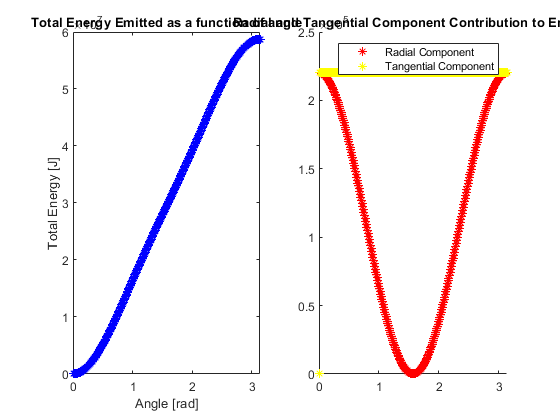

%now computing the integral of this to see where the total energy comes
%from being radiated from the particle.

%remember that integrals are just infinite sums. They are trivial to
%determine with modern computers. Let's rock.
k=2;
energy_emitted(1)=0;
for i=0:0.01:pi
    [radial_em4(k),tangential_em4(k)]=thomson_emission_coefficients(energy,time,...
            100,400*(10.^-9),particle_density,e_mass,e_charge,(180./pi)*i);
    energy_emitted(k)=energy_emitted(k-1)+sin(i)*(radial_em4(k)+tangential_em4(k));
    angle(k)=i;
    k=k+1;
end
    
%now, let's plot the energy emitted as a function of angle.
figure
subplot(1,2,1)
plot(angle,energy_emitted,'b*')
title('Total Energy Emitted as a function of angle')
xlabel('Angle [rad]')
ylabel('Total Energy [J]')
subplot(1,2,2)
hold on 
plot(angle,radial_em4,'r*')
plot(angle,tangential_em4,'y*')
title('Radial and Tangential Component Contribution to Energy')
legend('Radial Component','Tangential Component')
hold off

This ends example two regarding Thomson scattering, I hope it was insightfull and helps give a physical understanding of scattering along with a little bit of computational physics and modelling. 